# Figure 4A, 4C, S5A, S5E, S5F

**Load Data**

clear
[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);

dataDir = '..\..\FINAL DATA files';

load([dataDir filesep 'A048_data.mat'],'S','settings','allIF');
conditions = settings.conditions

framesPerHr = 60/12;
frameDrugAdded = 0;
frameEdU = 0;
timeStart = 0;

folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;



times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};

for i = 1:length(S)
   
    S(i).POI_realtime = S(i).POI/framesPerHr;
    
end

 drug_time = frameDrugAdded/framesPerHr;

**Gate cells**

for i = 1:length(S)
    dat = S(i);
    apcExpressGate = false(length(dat.POI(:,1)),1);
    apcGate = false(length(dat.POI(:,1)),1);
    apcGateAll = false(length(dat.POI(:,1)),1);
    cdkHighGate = false(length(dat.POI(:,1)),1);
crlGate = false(length(dat.POI(:,1)),1);

    for n = 1:length(dat.POI(:,1))
        if dat.POI(n,1) > 1 * framesPerHr & dat.POI(n,1) < numFrames - 1 * framesPerHr
            apcExpressGate(n) = nanmean(dat.apcAreaNormM(n,dat.POI(n,1) + [-1* framesPerHr: -.5* framesPerHr] )) > .5 & ...
                nanmean(dat.apcAreaNormM(n,dat.POI(n,1) + [round(.5* framesPerHr): 1* framesPerHr] )) < .1;
        end
        if dat.POI(n,1) + round(20*framesPerHr) <= numFrames 
            apcGate(n) = dat.apcNormM(n,dat.POI(n,1) + round(20*framesPerHr)) < .02;
            apcGateAll(n) = ~isnan(dat.apcNormM(n,dat.POI(n,1) + round(20*framesPerHr)));
        end
        if dat.POI(n,1) + round(6*framesPerHr) <= numFrames 
            cdkHighGate(n) = dat.cdk(n,dat.POI(n,1) + round(6*framesPerHr)) > .7;
        end
        if dat.POI(n,1) > 1 * framesPerHr & dat.POI(n,1) <numFrames - 1 * framesPerHr
            crlGate(n) = dat.crlNormAct(n,dat.POI(n,1) - 1 * framesPerHr) >  .5 & ...
               dat.crlNormAct(n,dat.POI(n,1) + 1 * framesPerHr) > .5;
        end

    end
    S(i).apcExpressGate = apcExpressGate;
    S(i).apcGate = apcGate;
    S(i).apcGateAll = apcGateAll;

   S(i).crlGate = crlGate;
        S(i).cdkHighGate = cdkHighGate;

end

4A left

 conds=[29 32];


colors = [.5 .5 .5; .6 .9 .2;.9 .4 .2];
linetype = {'-','-','--','--'};
timeGate = [0 20];

figure('unit','inches','position',[0 0 4 4])
hold on
axis square;
POI_align = 3;
for i=1:length(conds)
    c = conds(i);
    data = S(c);
   inds = ~isnan(data.POI(:,3)) & ~isnan(data.POI(:,1)) &...
        S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1) &...
        S(conds(i)).apcExpressGate & S(conds(i)).goodCdk;
 sum(inds)


    ydata = data.cdk(inds,:);
    POI = data.POI(inds,POI_align) ;
    
    [frames, medSig, semCRL] =get_mean_trace(ydata,POI,1);
    shadedErrorBar((frames)/framesPerHr,medSig,2*semCRL,'lineProps',{'Color',colors(i,:),'LineWidth',1.5,'linestyle',linetype(i)});
end

ans = 1870

ans = 988

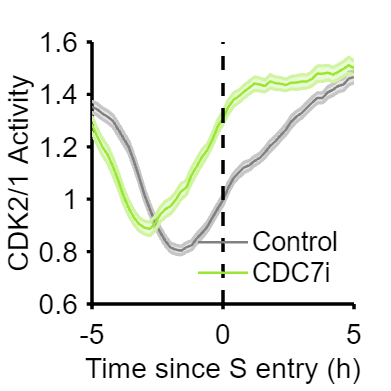


ylabel({'CDK2/1 Activity'});xlabel('Time since S entry (h)');
legend('Control','CDC7i','box','off','Location','southeast','fontsize',16);
set(gca,'linewidth',2,'fontsize',17)
xlim([-5 5]); 
ylim([.6 1.6]);

vline([0],'k--')

 % print_pdf(['fig_4A_left.pdf'])



4C

 conds=[29 22 32 25];


colors = [.5 .5 .5; .9 .2 .5; .6 .9 .2;.9 .4 .2];
linetype = {'-','-','--','--'};
timeGate = [0 20];

figure('unit','inches','position',[0 0 4 4])
hold on
axis square;
POI_align = 3;
for i=1:length(conds)
    c = conds(i);
    data = S(c);
   inds = ~isnan(data.POI(:,3)) & ~isnan(data.POI(:,1)) &...
        S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1) &...
        S(conds(i)).apcExpressGate & S(conds(i)).goodCdk;
 sum(inds)


    ydata = data.cdk(inds,:);
    POI = data.POI(inds,POI_align) ;
    
    [frames, medSig, semCRL] =get_mean_trace(ydata,POI,1);
    shadedErrorBar((frames)/framesPerHr,medSig,2*semCRL,'lineProps',{'Color',colors(i,:),'LineWidth',1.5,'linestyle',linetype(i)});
end

ans = 1870

ans = 1043

ans = 988

ans = 583

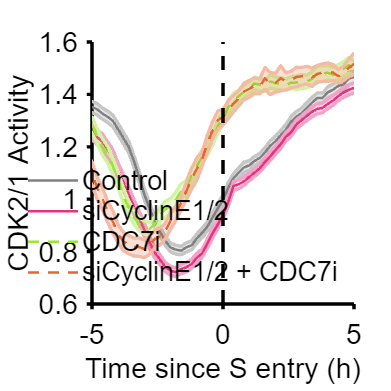


ylabel({'CDK2/1 Activity'});xlabel('Time since S entry (h)');
legend('Control','siCyclinE1/2','CDC7i','siCyclinE1/2 + CDC7i','box','off','Location','southeast','fontsize',16);
set(gca,'linewidth',2,'fontsize',17)
xlim([-5 5]); 
ylim([.6 1.6]);
vline([0],'k--')

 % print_pdf(['fig_4C.pdf'])



S5A

 conds=[29 32 ];
timeGate = [0 20];
% cols = [.6 .8 .1;.333 .302 .541;.51 .008 .388;.851 .012 .408;.941 .447 .282;.333 .302 .541; 1 .831 0; 1 .647 .671; .855 .384 .49; .647 .22 .376; .271 .035 .125; .525 .075 .788; .075 .322 .702];
cols = [.7 .7 .7;.6 .9 .2];
% [.6 .8 .1;.333 .302 .541;.51 .008 .388;.851 .012 .408;.941 .447 .282;.333 .302 .541; 1 .831 0; 1 .647 .671; .855 .384 .49; .647 .22 .376; .271 .035 .125; .525 .075 .788; .075 .322 .702];
figure('unit','inches','position',[0 0 4 4])
hold on
axis square;
POI_align = 1;
POI_cal = 3;
for i=1:length(conds)
    c = conds(i);
    data = S(c);
        inds=  S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1) &...
        S(conds(i)).apcExpressGate & S(conds(i)).goodCdk;

          sum(inds)


    event = data.POI(:,POI_cal);

    start = data.POI(:,POI_align);
    ends = data.traceStats(:,6);

   y = event- start ;
    lost = ends  - start ;
    y = y/framesPerHr; %y = time of POI_cal relative to POI_align
    lost = lost/framesPerHr; % lost = last frame relative to POI_align
    censor = isnan(y); %if y isnan, censor = 1
    y(censor) = lost(censor);
    y_filt = y(inds);
    censor_filt = censor(inds);
    [f,x] = ecdf(y_filt,'Censoring',censor_filt);
    if isempty(f)
        f = 0;
        x = 0;
    end
    y_max = max(y_filt(censor_filt));
    if x(end) < y_max
        x(end+1) = y_max;
        f(end + 1) = f(end);
    end
    if f(end) == 1
        x(end+1) = 1000;
        f(end + 1) = f(end);
    end
     if x(1) ~= 0
        x0 = 0;
        f0 = 0;
        f = cat(1,f0,f);
        x = cat(1,x0,x);
     end 

    plot(x,f,'Color',cols(i,:),'linewidth',2);
end

ans = 4859

ans = 2760

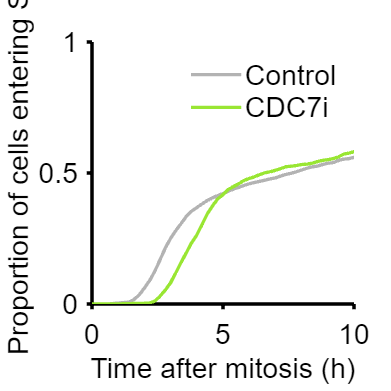


ylabel({'Proportion of cells entering S'});xlabel('Time after mitosis (h)');
legend('Control','CDC7i','box','off','fontsize',17);
set(gca,'fontsize',17,'linewidth',2)
xlim([0 10]); 
ylim([.0 1]);


 % print_pdf(['fig_S5A.pdf'])

S5E

conds=[29 22 32 25];


colors = [.1 .4 1; .9 .2 .5; .6 .9 .2;.9 .4 .2];
clear cols
POI_align = 3;
ally = [];
groups = [];
timeGate = [0 20];

for i=1:length(conds)
    c = conds(i);
    data = S(c);
      inds = ~isnan(data.POI(:,3)) & ~isnan(data.POI(:,1)) &...
        S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1) & S(conds(i)).apcExpressGate & S(conds(i)).goodCdk;
 sum(inds)


    yvals = (data.POI_realtime(inds,3) - data.POI_realtime(inds,1));
    yvals = yvals(yvals < 2000 & yvals >= 0);
    ally = [ally; yvals];
    groups = [groups; repmat(i,size(yvals))];
    meang1(i) = mean(yvals);
    length(yvals);
    cols(i,1) = ({colors(i,:)}');
    groupcol = repmat([colors([1:i],:)],1,1);
 

end

ans = 1870

ans = 1043

ans = 988

ans = 583

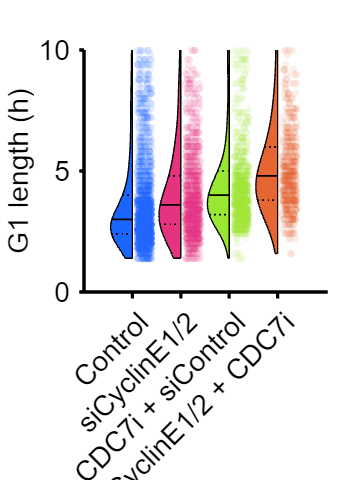


figure('Units', 'Inches', 'Position', [0, 0, 3, 4])

h = violinPlot((ally),'groups',groups, 'showMM',6,'histOpt',1,'divFactor',.5,'histOri','left','widthDiv',[2 1],'color','black');

set(h{1},{'FaceColor'},cols)
hold on
jit = 0.3*rand(size(groups)) + .1;
scatter(groups+jit, (ally), 20,groupcol(groups,:),'filled','MarkerFaceAlpha',.1);
ylabel([ 'G1 length (h)'])


xticklabels({'Control','siCyclinE1/2','CDC7i + siControl','siCyclinE1/2 + CDC7i'})
ylim([0 10])
 xtickangle(45)
 set(gca,'linewidth',2,'fontsize',17)
axis square




p=mediantest(ally(groups==1),ally(groups==2))

p = 3.9686e-22

p=mediantest(ally(groups==3),ally(groups==4))

p = 2.3739e-16

 % print_pdf(['fig_S5E.pdf'])

S5F

conds=[29 22 32 25];


colors = [.1 .4 1; .9 .2 .5; .6 .9 .2;.9 .4 .2];
linetype = {'-','-','--','--'};
timeGate = [0 20];

figure('unit','inches','position',[0 0 3 3])
hold on
axis square;
POI_align =1;
for i=1:length(conds)
    c = conds(i);
    data = S(c);
   inds = ~isnan(data.POI(:,3)) & ~isnan(data.POI(:,1)) &...
        S(conds(i)).POI_realtime(:,1) <= timeGate(2) & S(conds(i)).POI_realtime(:,1) >= timeGate(1) &...
        S(conds(i)).apcExpressGate & S(conds(i)).goodCdk;
 sum(inds)


    ydata = data.cdk(inds,:);
    POI = data.POI(inds,POI_align) ;
    
    [frames, medSig, semCRL] =get_mean_trace(ydata,POI,1);
    shadedErrorBar((frames)/framesPerHr,medSig,2*semCRL,'lineProps',{'Color',colors(i,:),'LineWidth',1.5,'linestyle',linetype(i)});
end

ans = 1870

ans = 1043

ans = 988

ans = 583

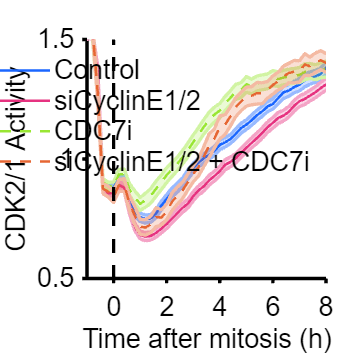


ylabel({'CDK2/1 Activity'});xlabel('Time after mitosis (h)');
legend('Control','siCyclinE1/2','CDC7i','siCyclinE1/2 + CDC7i','box','off','Location','north','fontsize',16);
set(gca,'linewidth',2,'fontsize',16)
xlim([-1 8]); 
ylim([.5 1.5]);
vline([0],'k--')

 % print_pdf(['fig_S5F.pdf'])